# Data analysis of localization confidence

- Does confidence reflect performance? Check correlation between error and confidence

- Is confidence modulated by cue discrepancy and cue reliability? Plot perceptual and causal confidence as a function of discrepancy (congruent, a bit incongruent, very incongruent trials); lines: low and high visual reliability

- Do people report lower confidence for incongruent trials despite identical perceptual and causal decisions? Compare confidence of perceptual and causal metamers

clear; clc; close all;
sub_slc     = 1;
ses_slc     = 1;

% manage path
cur_dir      = pwd;
[project_dir, ~]= fileparts(fileparts(cur_dir));
out_dir      = fullfile(cur_dir, 's1Fig');
addpath(genpath(fullfile(project_dir,'func')))
data_dir     = fullfile(project_dir, 'data','biLoc');
if ~exist(out_dir,'dir') mkdir(out_dir); end

% organize data
[org_resp, org_conf, org_err, ExpInfo] = org_data(sub_slc,ses_slc,'biLoc');

% organize by discrepancy
aud_locs = ExpInfo.speakerLocPixel(ExpInfo.audIdx);
conf_by_diff = org_by_diffs(org_conf, aud_locs); % {diff} cue x reliability x rep 

% conditions
seq         = ExpInfo.randAVIdx;
audIdx      = ExpInfo.audIdx;
visIdx      = ExpInfo.visIdx;
cueIdx      = ExpInfo.cueIdx;
visReliIdx  = ExpInfo.visReliIdx;
num_rep     = ExpInfo.nRep;
cue_label   = {'Post-cue: A','Post-cue: V'};
rel_label   = {'High visual reliability','Low visual reliability'};
vis_locs    = round(ExpInfo.targetPixel);
diffs       = zeros(length(aud_locs), length(vis_locs));
for i = 1:length(aud_locs)
    for j = 1:length(vis_locs)
        diffs(i, j) = aud_locs(i) - aud_locs(j);
    end
end
diff_locs   = unique(abs(diffs));

## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    251, 154, 153]./255; % light red


## Sanity check: localization response

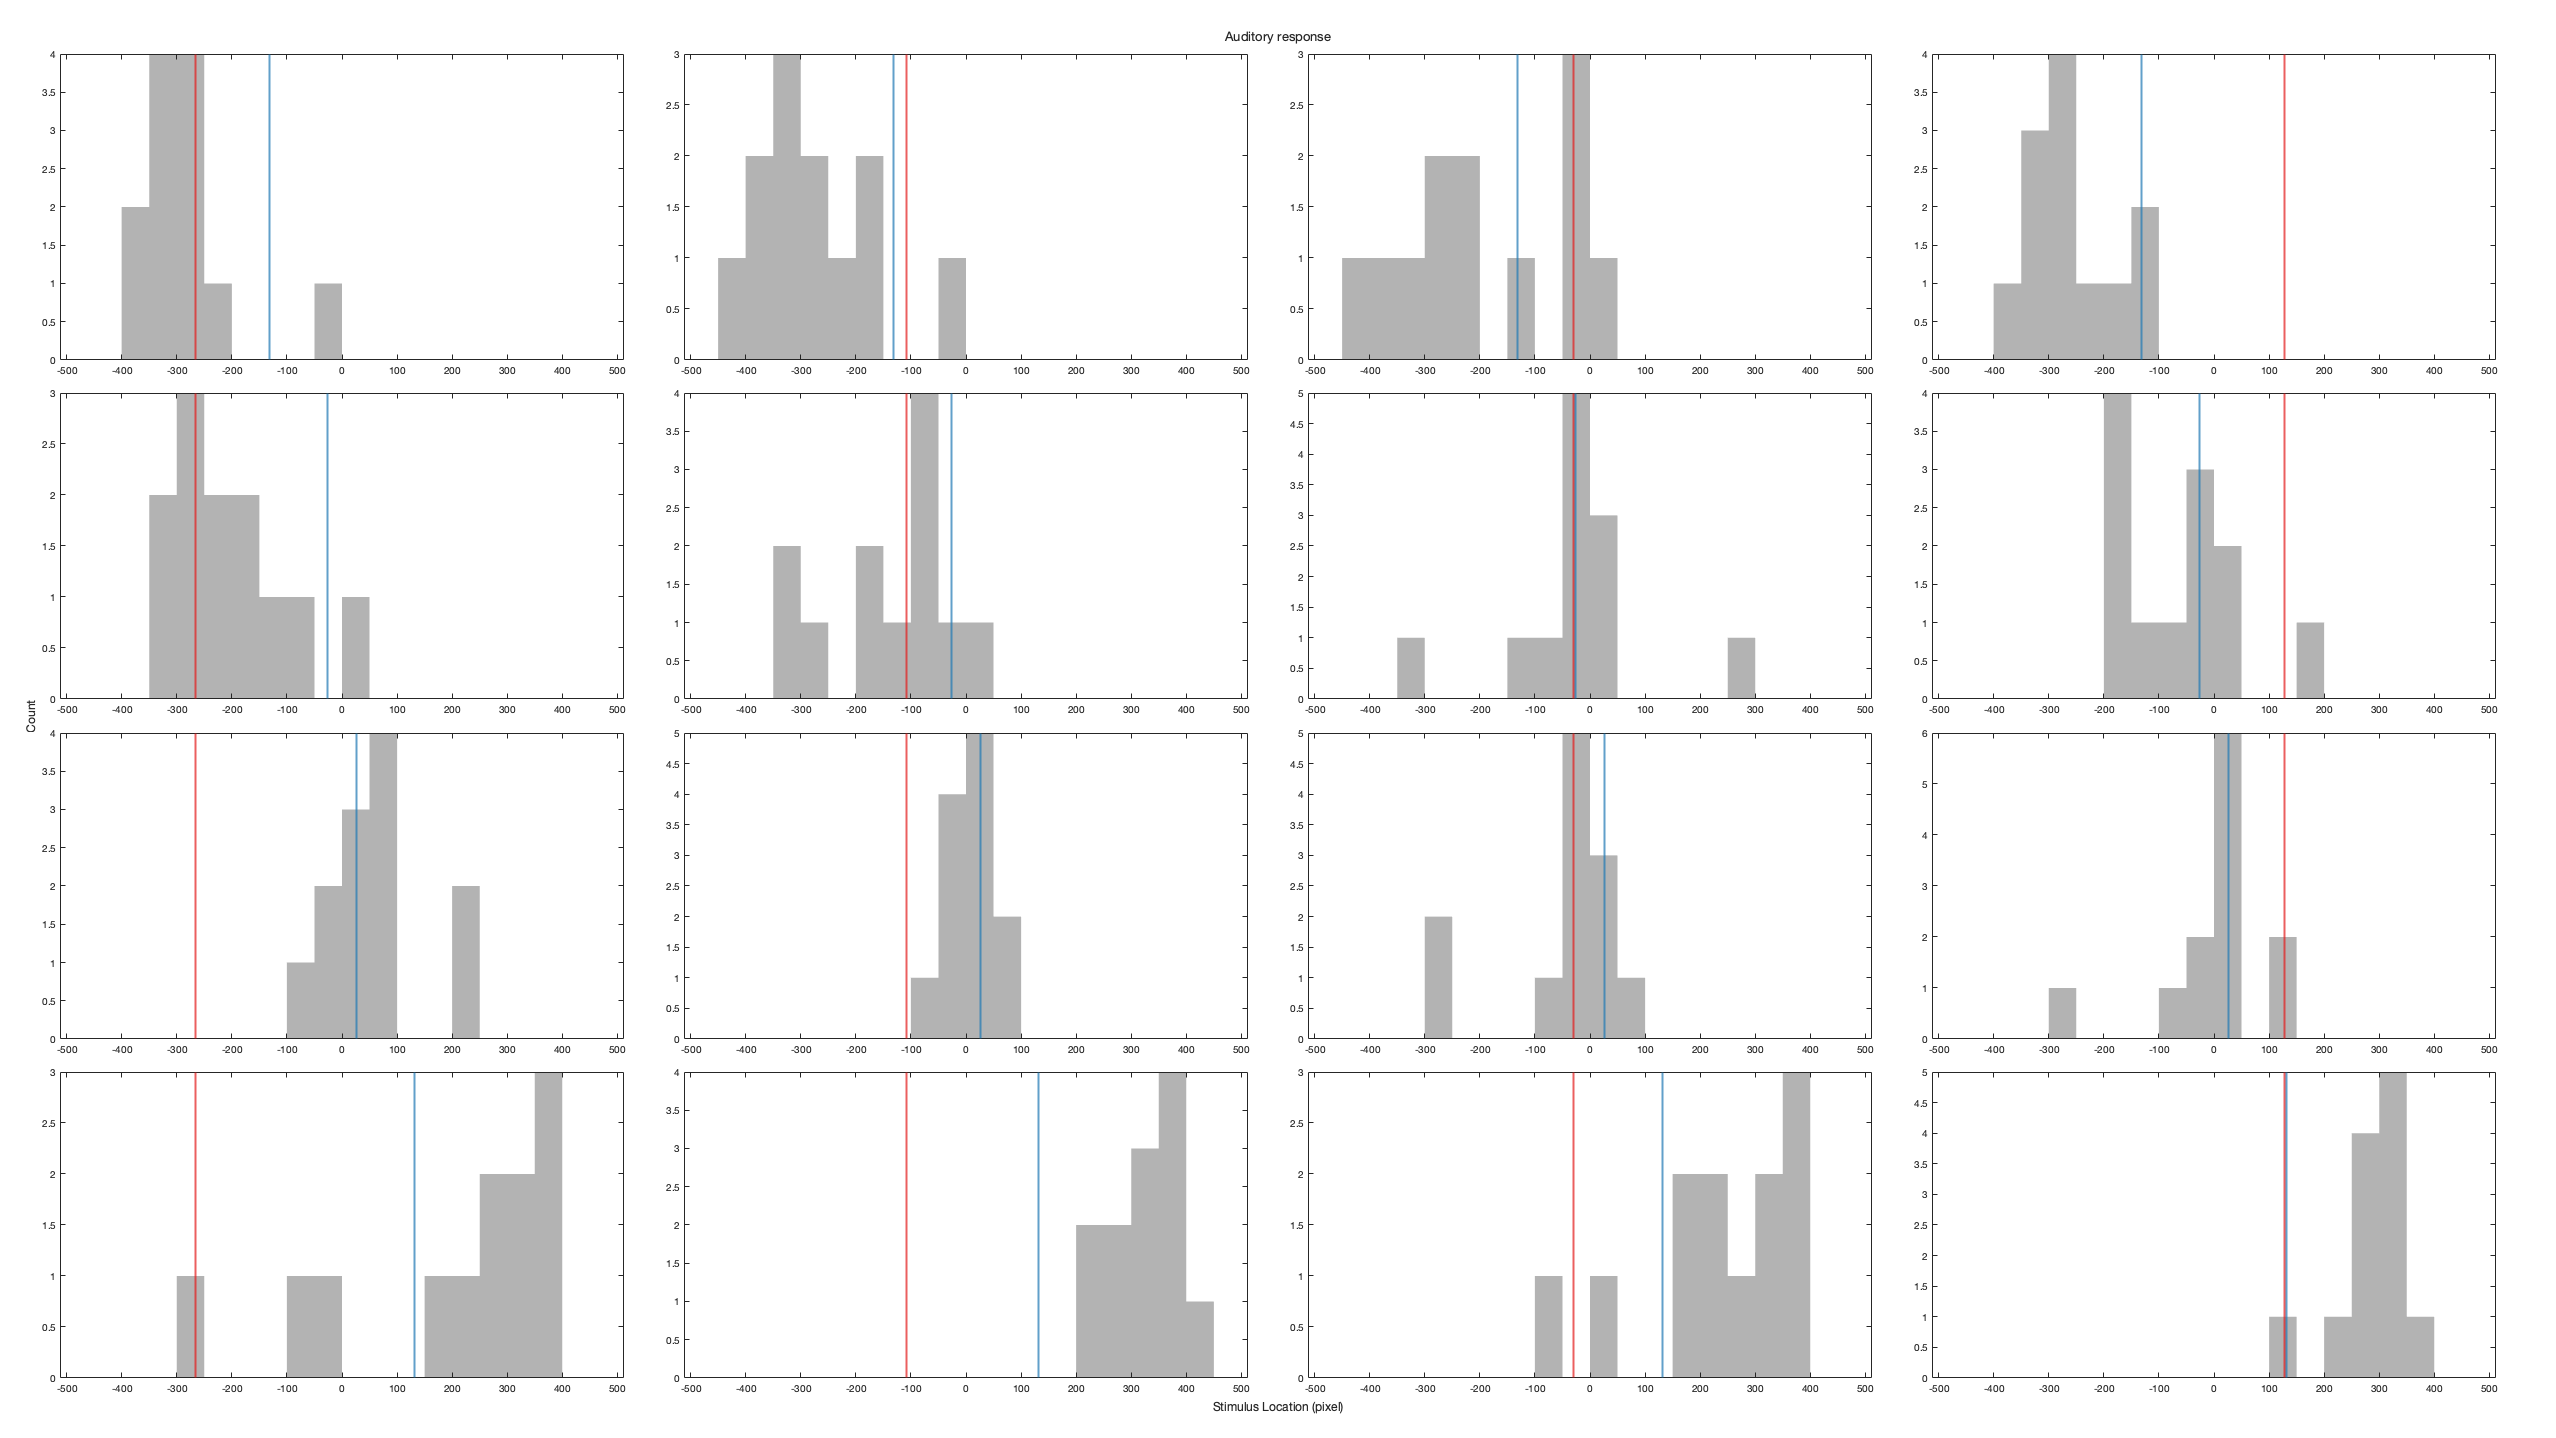

figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Auditory response')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(org_resp(a, v, 1, :, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',50);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-512, 512])
    end
end

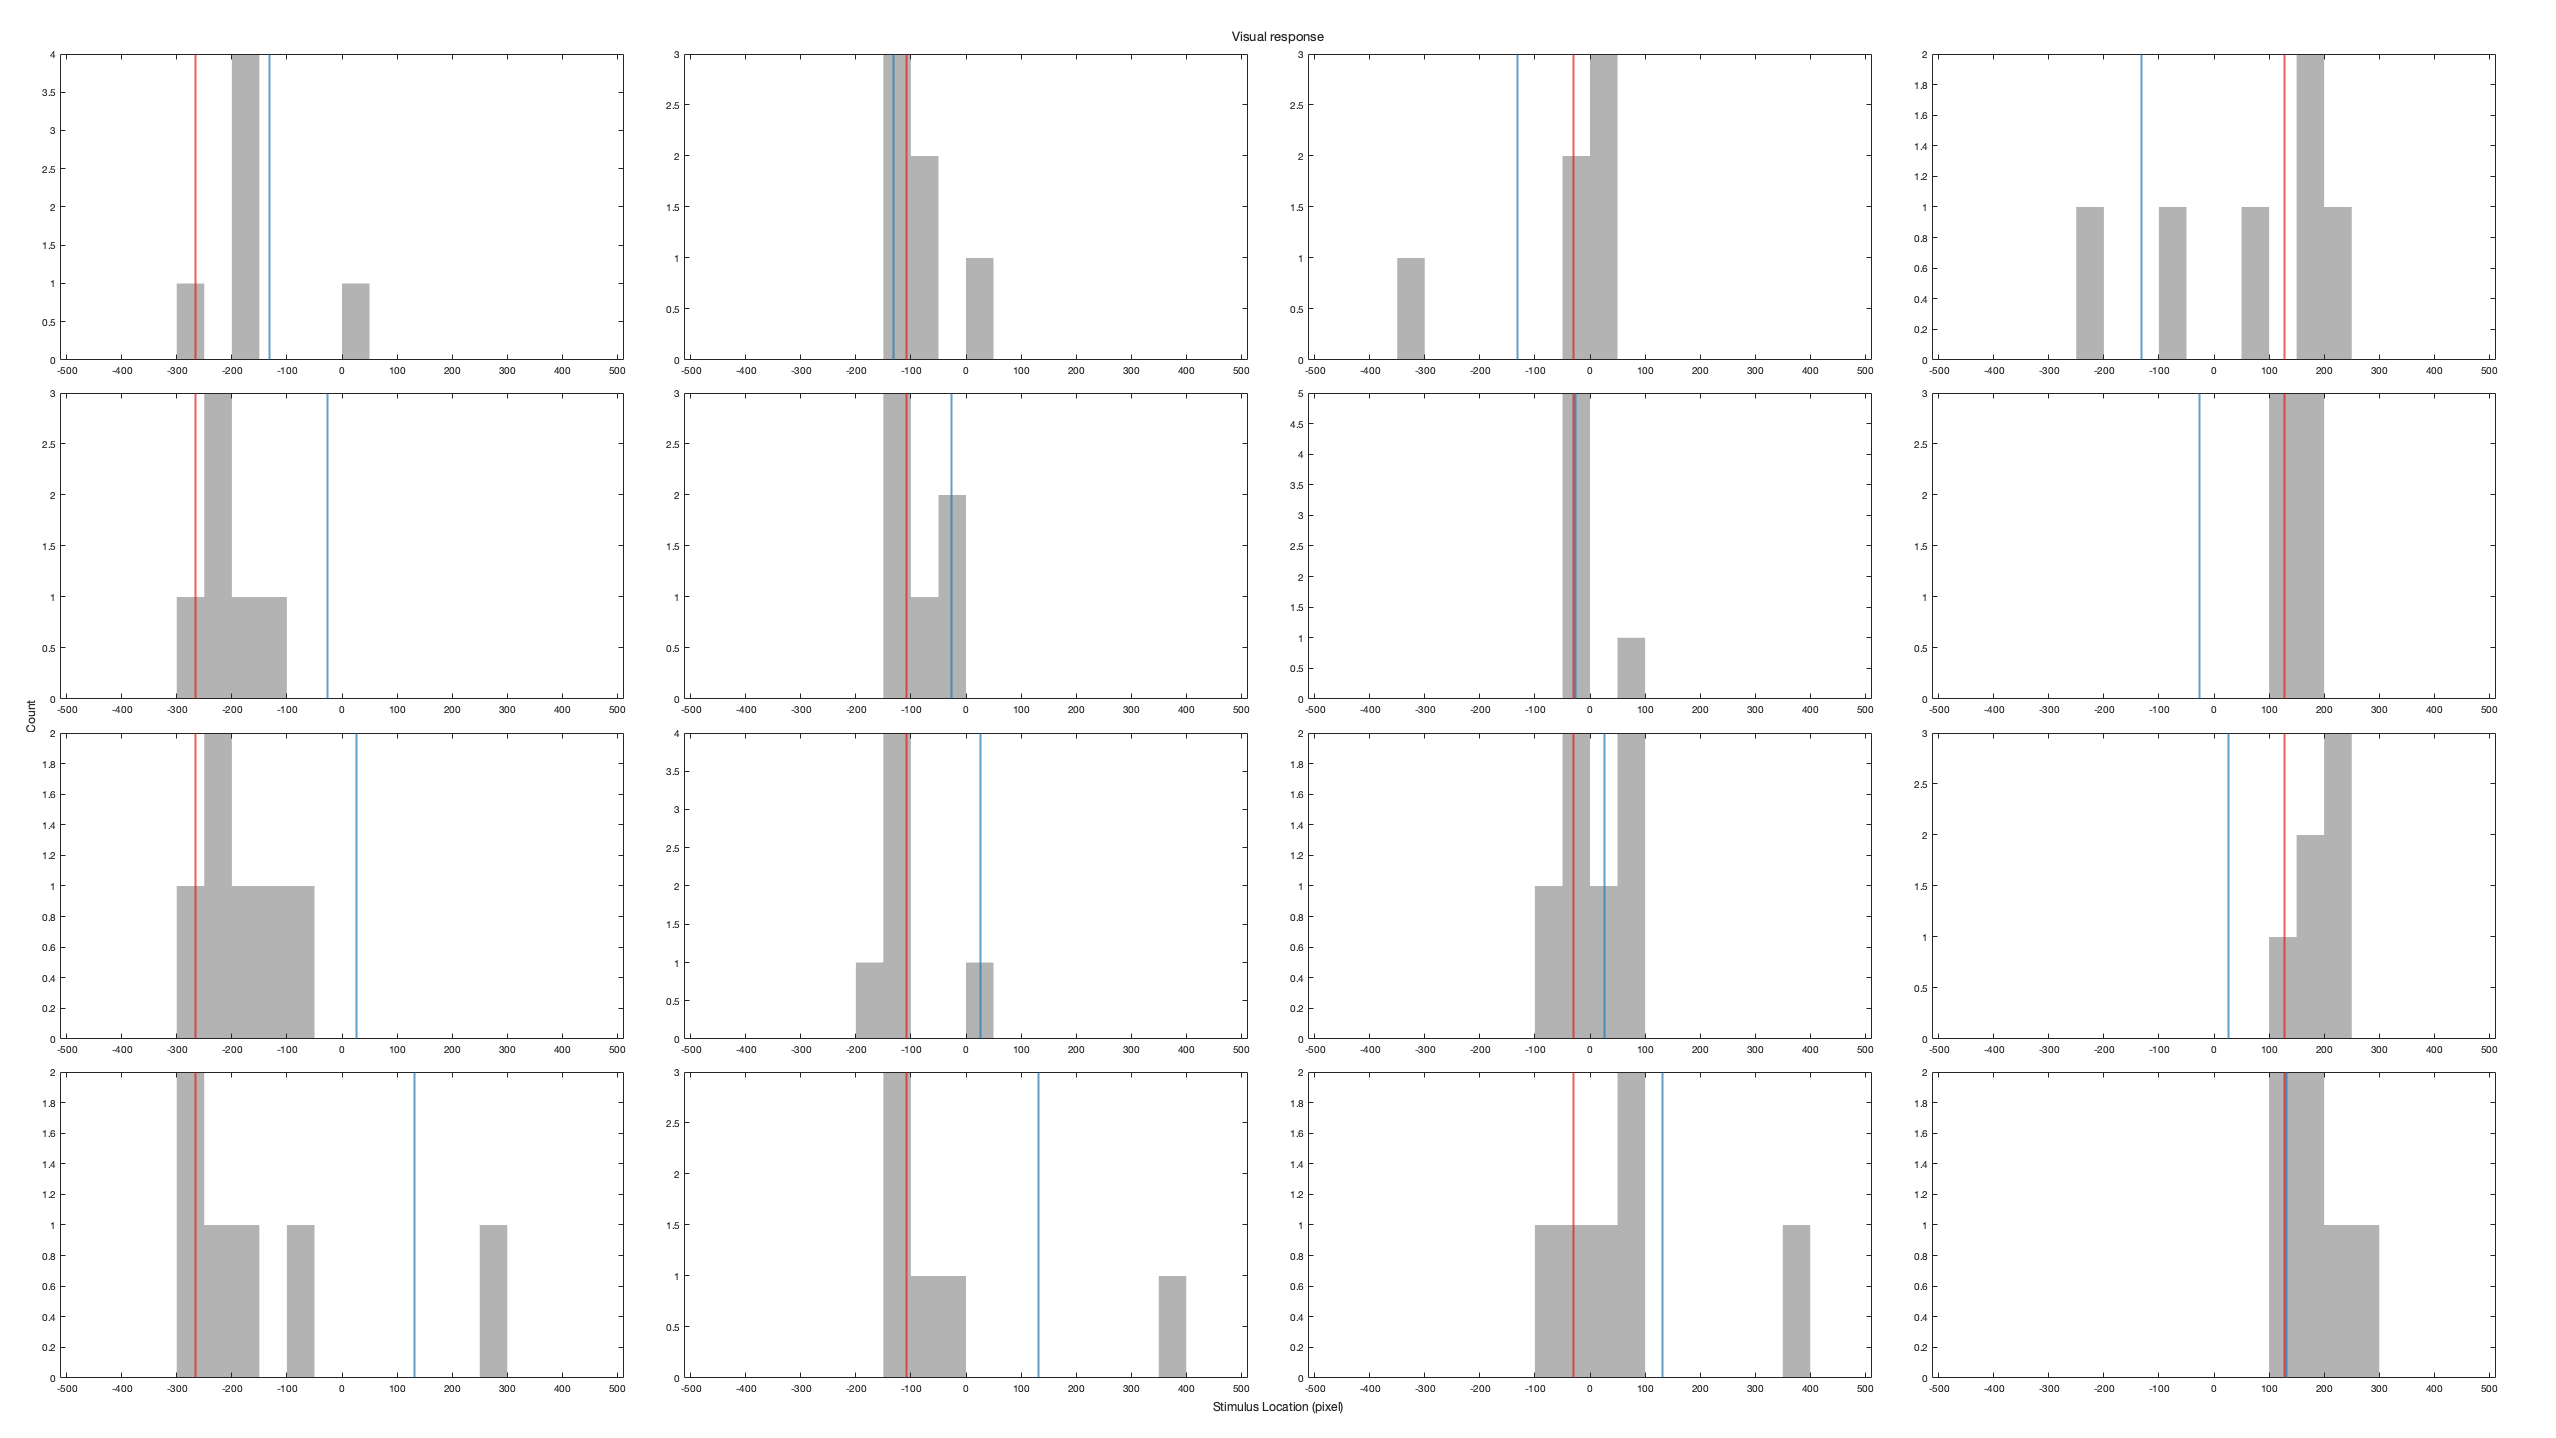



figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
t = tiledlayout(4, 4);
title(t, 'Visual response')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';
% Loop over each auditory index
for a = 1:length(audIdx)
    % Loop over each visual index
    for v = 1:length(visIdx)
         curr_resp = squeeze(org_resp(a, v, 2, 2, :));
         nexttile
         h = histogram(curr_resp, numel(curr_resp),'BinWidth',50);
         h.FaceColor = repmat(0.5, 1, 3); 
         h.EdgeColor = 'none';

         xline(aud_locs(a),'LineWidth',lw,'Color',clt(1,:))
         xline(vis_locs(v),'LineWidth',lw,'Color',clt(2,:))

         xlim([-512, 512])
    end
end

## Sanity check: bias in congruent trials

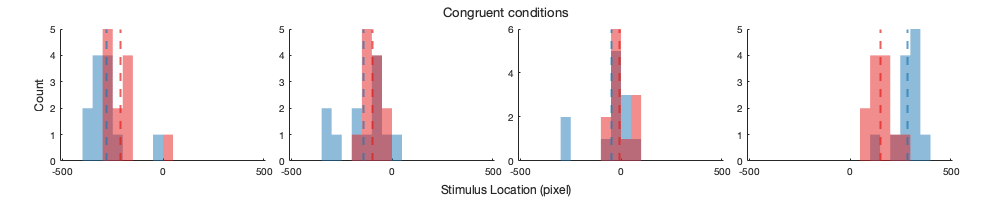

figure
set(gcf, 'Position',[0 0 1000 200])
hold on
t = tiledlayout(1, 4);
title(t, 'Congruent conditions')
xlabel(t, 'Stimulus Location (pixel)');
ylabel(t, 'Count');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for ii = 1:numel(audIdx)

    nexttile;
    hold on

    for rr = 1:numel(cueIdx)

        curr_resp = squeeze(org_resp(ii, ii, rr, :, :));
        h = histogram(curr_resp, numel(curr_resp),'FaceAlpha',0.5,'BinWidth',50);
        h.FaceColor = clt(rr,:);
        h.EdgeColor = 'none';

        mean_congruent(ii, rr) = mean(curr_resp,'all');
        std_congruent(ii, rr)  = std(curr_resp,[],'all');
        xline(mean_congruent(ii, rr),'--','LineWidth',lw,'Color',clt(rr,:))

        xlim([-512, 512])
   end

end

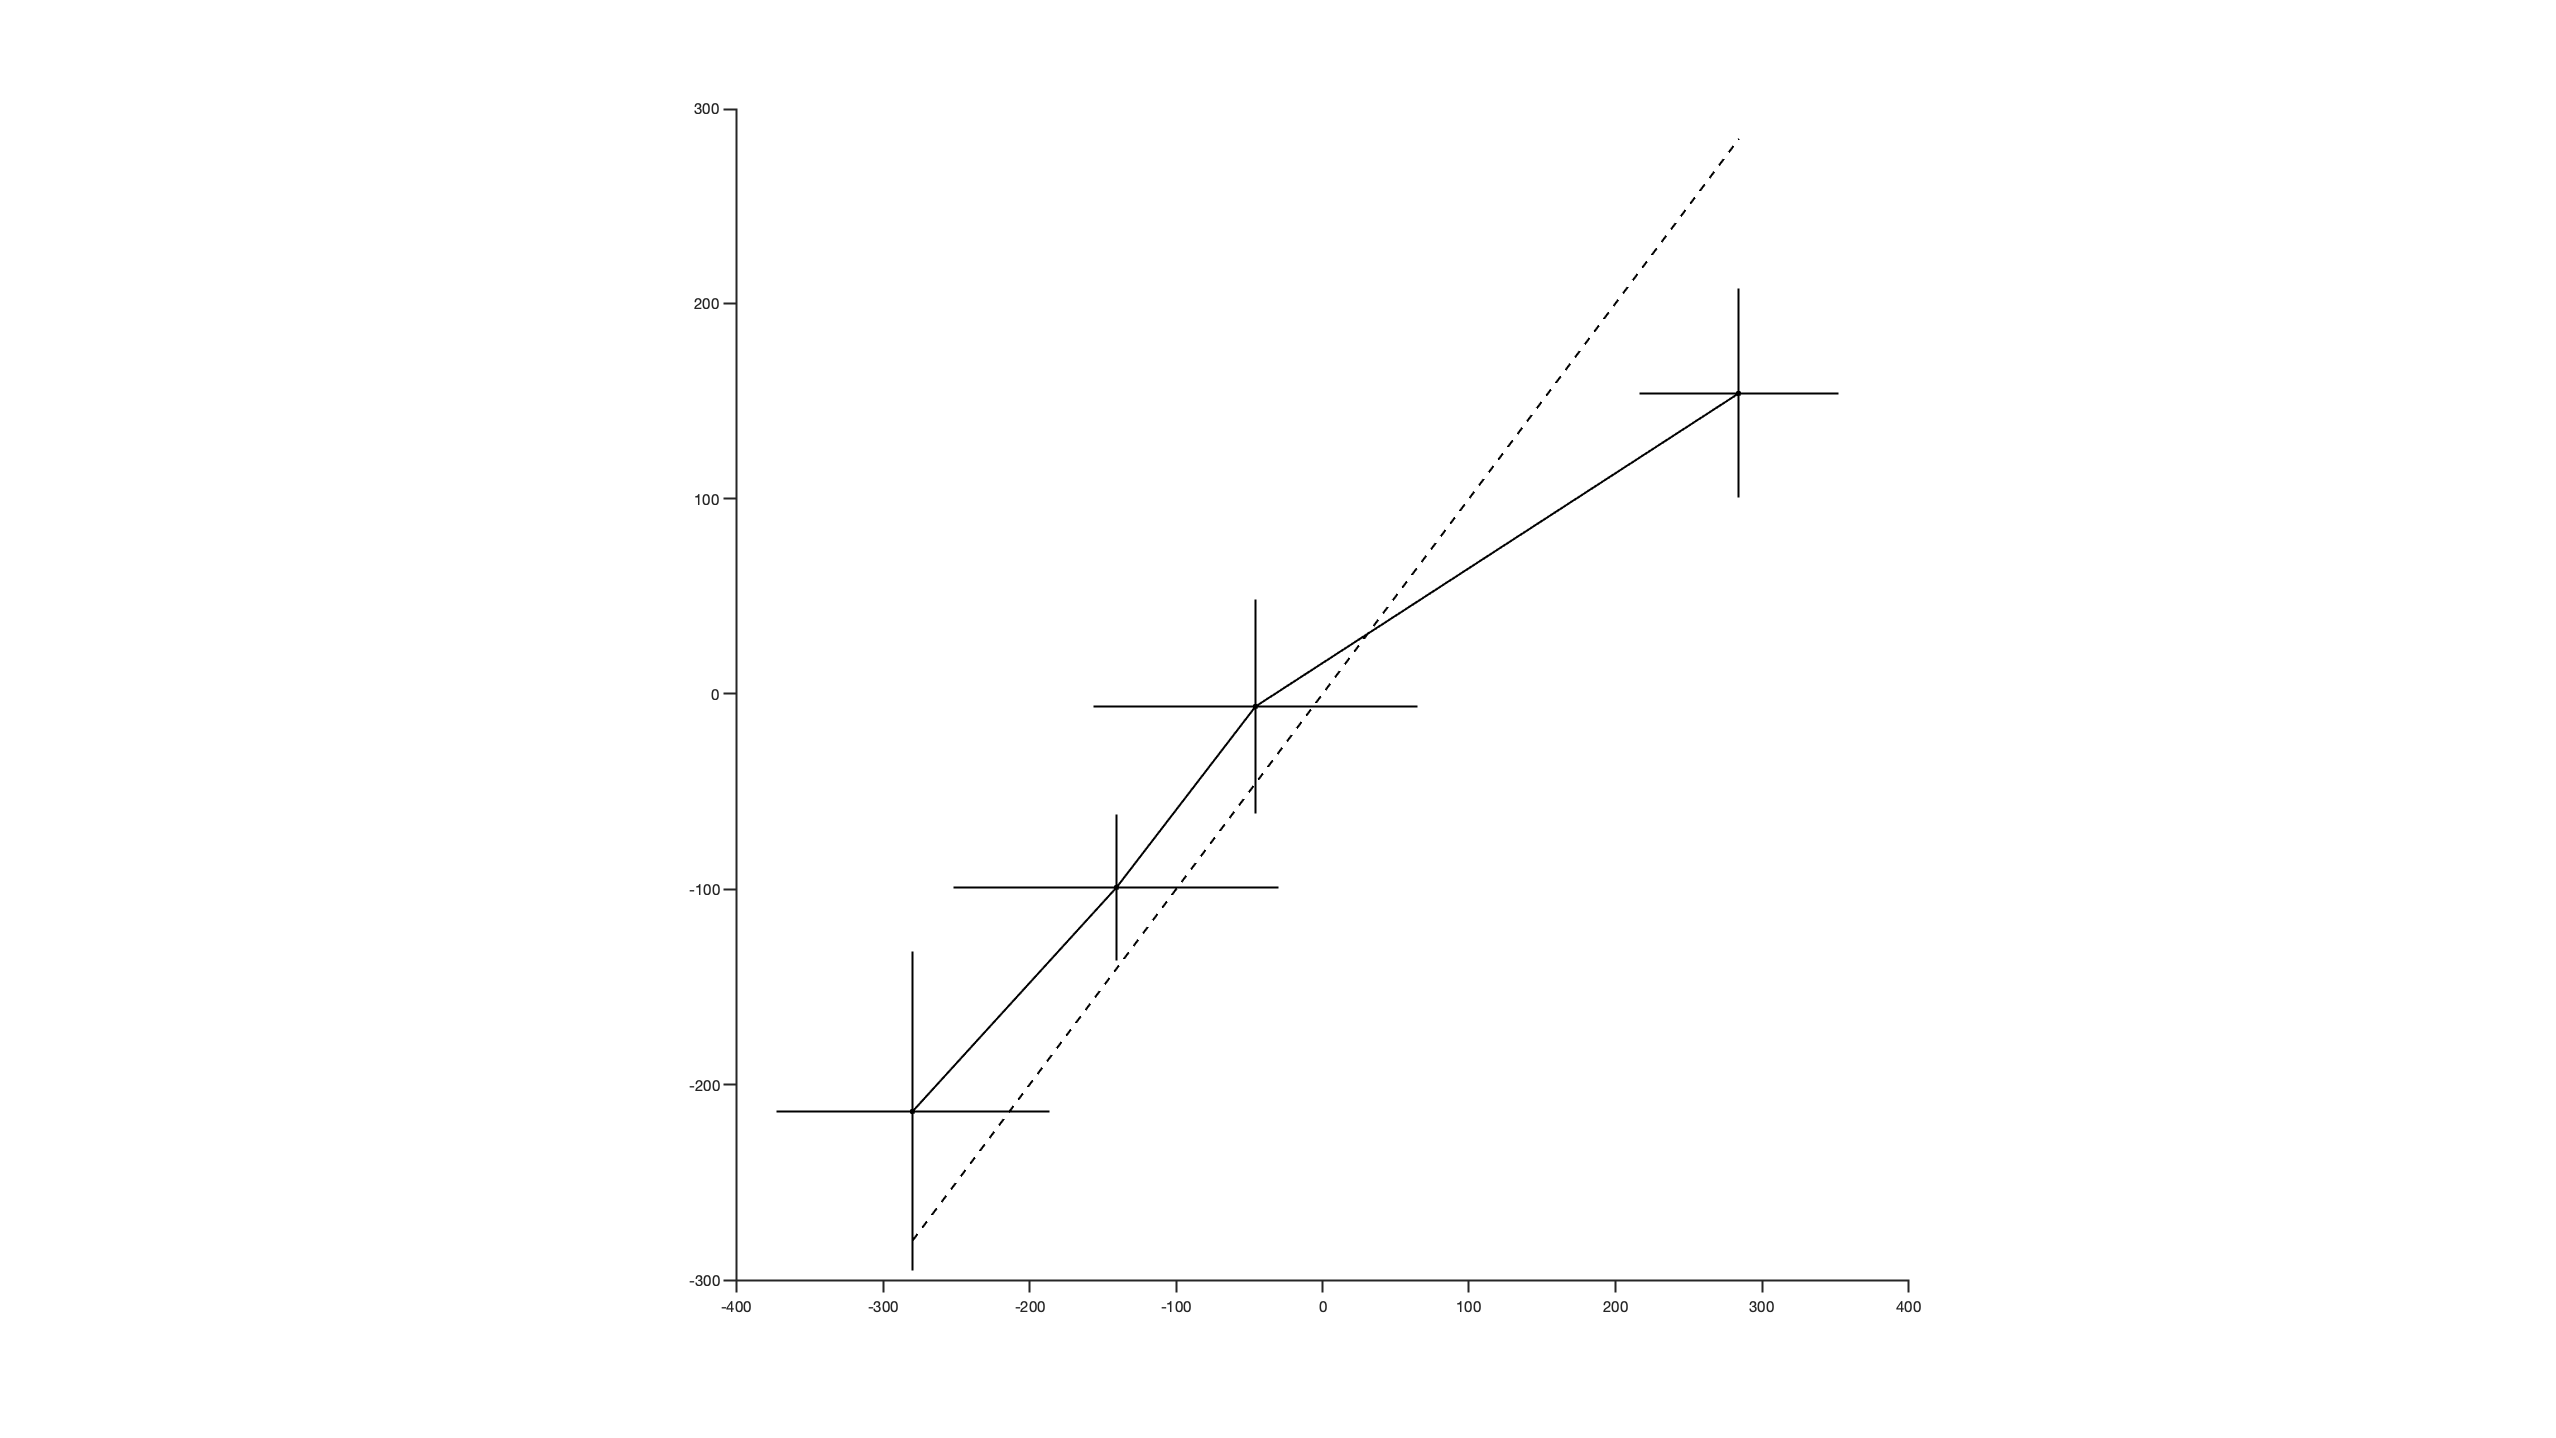



figure
set(gcf, 'Position', get(0, 'Screensize')); hold on
set(gca, 'LineWidth', lw, 'FontSize', fontSZ, 'TickDir', 'out')
axis equal; axis square

scatter(mean_congruent(:,1),mean_congruent(:,2),'filled','k')
e1 = errorbar(mean_congruent(:,1), mean_congruent(:,2), std_congruent(:,2),'k','LineWidth',lw);
e2 = errorbar(mean_congruent(:,1), mean_congruent(:,2), std_congruent(:,1), 'k','horizontal','LineWidth',lw);
e1.CapSize = 0;
e2.CapSize = 0;
plot(max(mean_congruent,[],"all"))
maxV = max(mean_congruent(:));
minV = min(mean_congruent(:));
plot([minV, maxV],[minV, maxV],'k--','LineWidth',lw)

## Correlation between error and confidence?

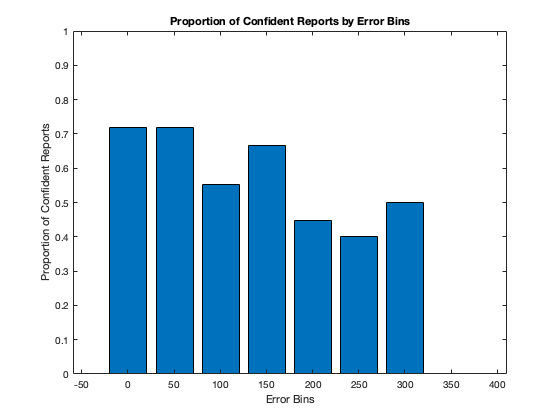

% Define bin width
binWidth = 50;

% Define range for bins
minError = min(org_err(:));
maxError = max(org_err(:));

% Create bins
bins = minError:binWidth:maxError;

% Initialize arrays to store proportions
numBins = numel(bins) - 1;
proportions = zeros(numBins, 1);

% Iterate over bins
for i = 1:numBins
    % Find indices of error values falling within the current bin
    indices = find(org_err >= bins(i) & org_err < bins(i+1));
    
    % Count total number of trials in this bin
    totalTrials = numel(indices);
    
    % Count number of confident reports in this bin
    confidentReports = sum(org_conf(indices) == 1);
    
    % Calculate proportion of confident reports
    if totalTrials > 0
        proportions(i) = confidentReports / totalTrials;
    else
        proportions(i) = 0; % To handle division by zero if no trials in the bin
    end
end

% Plot proportions
figure;
bar(bins(1:end-1), proportions)
ylim([0, 1])
xlabel('Error Bins')
ylabel('Proportion of Confident Reports')
title('Proportion of Confident Reports by Error Bins')

## Is confidence modulated by cue discrepancy and cue reliability?

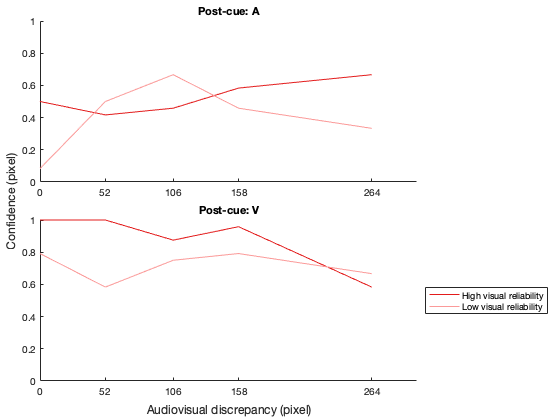

figure; hold on

t = tiledlayout(2, 1);
xlabel(t, 'Audiovisual discrepancy (pixel)');
ylabel(t, 'Confidence (pixel)');
t.TileSpacing = 'compact';
t.Padding = 'compact';

for cue = 1:numel(cueIdx)
    nexttile
    title(cue_label{cue})
    hold on
    for rel = 1:numel(visReliIdx)
        p_conf = NaN(1, numel(diff_locs));
        for diff = 1:numel(diff_locs)
            i_conf = squeeze(conf_by_diff{diff}(cue, rel, :))';
            p_conf(diff) = sum(i_conf)/numel(i_conf);
        end
        plot(diff_locs, p_conf, 'Color',clt(rel+1,:))
        ylim([0, 1])
    end
    xticks(diff_locs)
end
legend(rel_label, 'Location', 'eastoutside');